direction_names = ["FF","BF","FB","BB"];

s = sysf_two_link_lowRe;
nlinks = length(s.geometry.linklengths);

s = ensure_connection_and_metric(s); % required for create_grids
s = create_grids(s)
a_grid = s.grid.eval{1};
adot_grid = s.grid.eval{1}*0.1;

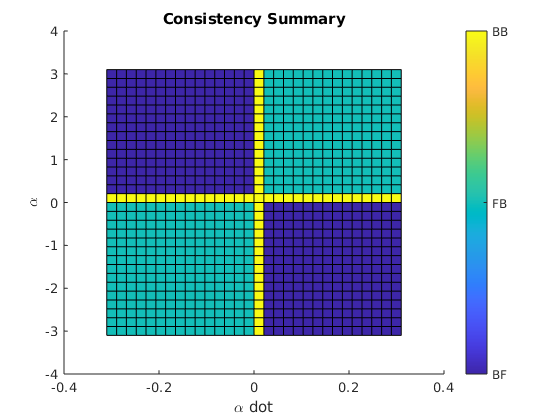

% find which system is consistent when
[system_map, count] = identify_piecewise_system(s, adot_grid);

% look at symmetry and missing/redundant areas
figure(5);
clf(5);
title("Consistency Summary");
xlabel("\alpha dot");
ylabel("\alpha");
surface(adot_grid, a_grid, system_map);
colorbar('Ticks',[1, 2, 3, 4],...
         'TickLabels',direction_names)

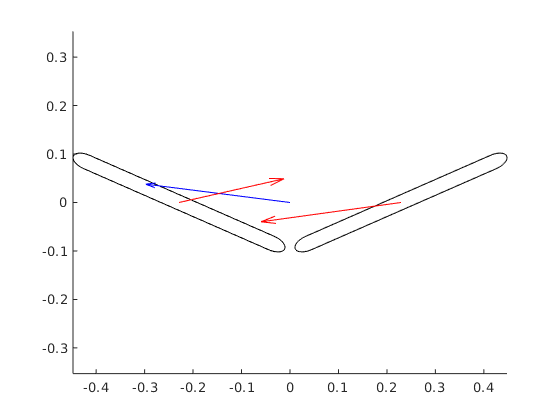

% get a body velocity
i = 20; j = 30;
bvel = apply_piecewise_system(s, system_map, 2, 0.1);

% get link velocities
lvel = zeros(nlinks, 3); % 3 is x y theta

% get Jfull(alpha)
[~, ~, J_full, ~, ~] = N_link_chain(s.geometry, a_grid(i));

for link = 1:nlinks
    lvel(link, :) = J_full{link} * [bvel; adot_grid(j)];
end

% plot
velocity_diagram(s, lvel, bvel, a_grid(i), adot_grid(j), 0, 0);

% define gait functions
% entry 1: anonymous function for a(t)
% entry 2: anonymous function for adot(t) (derivative of a(t))
centered_gait = {@(t) 1 * sin(t), @(t) 1 * cos(t)};
offset_gait = {@(t) 1 + 1 * sin(t), @(t) 1 * cos(t)};
offset_gait2 = {@(t) -1 + 1 * sin(t), @(t) 1 * cos(t)};
tiny_gait = {@(t) 0.5 * sin(t), @(t) 0.5 * cos(t)};

% apply ODE solver
[t_solution, g_solution] = asym_solve_gait(s, offset_gait, system_map);
offset_gait_displacement = g_solution(size(g_solution,1),:)

offset_gait_displacement =    -0.0899    0.0118   -0.2172



[t_solution, g_solution] = asym_solve_gait(s, offset_gait2, system_map);
offset_gait2_displacement = g_solution(size(g_solution,1),:)

offset_gait2_displacement =    -0.0904   -0.0078    0.2172



[t_solution, g_solution] = asym_solve_gait(s, centered_gait, system_map);
centered_gait_displacement = g_solution(size(g_solution,1),:)

centered_gait_displacement =    -0.0671    0.0012   -0.0004



[t_solution, g_solution] = asym_solve_gait(s, tiny_gait, system_map);
tiny_gait_displacement = g_solution(size(g_solution,1),:)

tiny_gait_displacement =    -0.0183    0.0000   -0.0001


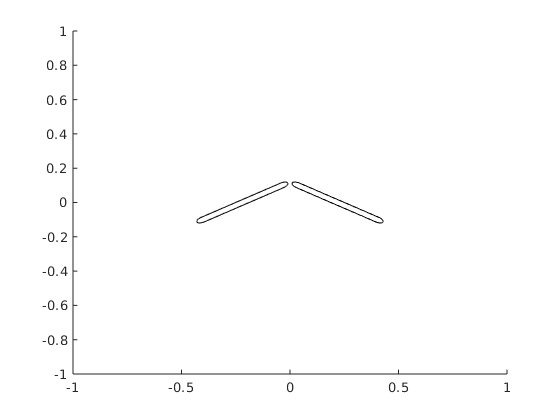

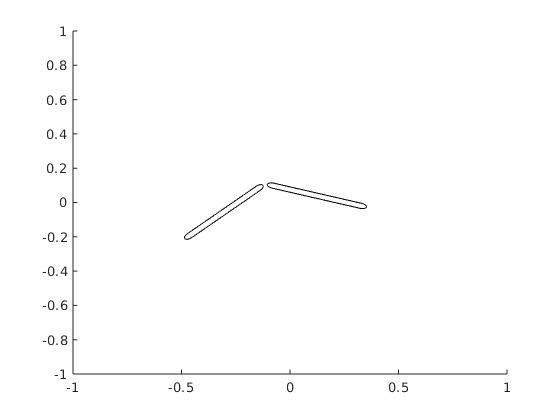

% record movie
figure()
axis manual
ax = gca;
ax.NextPlot = 'replaceChildren';
xlim([-1, 1]);
ylim([-1, 1]);

nframes = size(t_solution);
F = struct('cdata',[],'colormap',[]); % reset length of struct
F(nframes) = struct('cdata',[],'colormap',[]);
for frame = 1:nframes
    g = g_solution(frame, :);
    t = t_solution(frame);
    B = vec_to_mat_SE2(g) * fat_chain(s.geometry, gait{1}(t));
    cla
    hold on
    patch(B(1,:),B(2,:),[1 0 0])
    drawnow
    F(frame) = getframe;
end

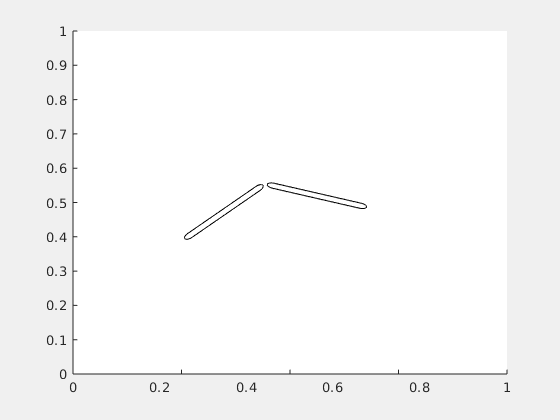

% play movie
figure('visible','on') %forces animation visible in live script
movie(F);

% write movie
% v = VideoWriter('AsymmetricFriction/animation_test_2link.avi');
% open(v);
% writeVideo(v, F);
% close(v);

% It's animating something!
% Things to do:
% - play around with different gaits
% - have body origin path traced out during animation
% - add motion blur
% - test with no-scales snake (physics check)
% - compare animation to physical intuition
%   (make sure scales are going in the correct direction)
% - move animation to function